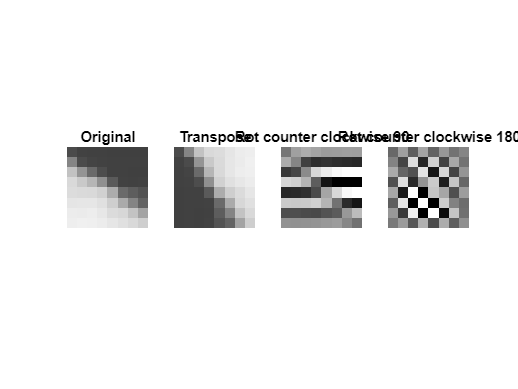

clear
clc

load('hall.mat');
hall_gray_preproc = double(hall_gray(1:8, 17:24))-128;

hall_gray_DCT = dct2(hall_gray_preproc);
hall_gray_DCT_tp = transpose(hall_gray_DCT);
hall_gray_DCT_rot90 = rot90(hall_gray_DCT);
hall_gray_DCT_rot180 = rot90(hall_gray_DCT,2);

hall_gray_tp = idct2(hall_gray_DCT_tp);
hall_gray_rot90 = idct2(hall_gray_DCT_rot90);
hall_gray_rot180 = idct2(hall_gray_DCT_rot180);

subplot(1,4,1);
imshow(hall_gray(1:8, 17:24));
title('Original');
subplot(1,4,2);
imshow(uint8(hall_gray_tp + 128));
title('Transpose');
subplot(1,4,3);
imshow(uint8(hall_gray_rot90 + 128));
title('Rot counter clockwise 90');
subplot(1,4,4);
imshow(uint8(hall_gray_rot180 + 128));
title('Rot counter clockwise 180');